# Bank Dataset

**Author: CARLOS M N**

**DNI: XXXXXXXX-X**

Clear workspace

clear all; clc; close all;

## Initialize variables

Load tables

training_set = readtable('bank-sample.csv')

training_set = 2000×17 table
    age          job             marital         education      default    balance    housing     loan        contact       day     month     duration    campaign    pdays    previous     poutcome      subscribed
    ___    ________________    ____________    _____________    _______    _______    _______    _______    ____________    ___    _______    ________    ________    _____    ________    ___________

test_set = readtable('bank-sample-test.csv');

Transform dates

training_set.date = datenum(strcat(num2str(training_set.day),training_set.month),'ddmmm');

test_set.date = datenum(strcat(num2str(test_set.day),test_set.month),'ddmmm');

Transform logarithmic variables

training_set.balance  = log(max(training_set.balance,1));
training_set.duration = log(training_set.duration + 1);

test_set.balance  = log(max(test_set.balance,1));
test_set.duration = log(test_set.duration + 1);

Transform categorical variables

training_set.job       = categorical(training_set.job);
training_set.marital   = categorical(training_set.marital);
training_set.education = categorical(training_set.education);
training_set.default   = categorical(training_set.default);
training_set.housing   = categorical(training_set.housing);
training_set.loan      = categorical(training_set.loan);
training_set.contact   = categorical(training_set.contact);
training_set.month     = categorical(training_set.month);
training_set.month     = reordercats(training_set.month, ["jan","feb","mar","apr","may","jun","jul","aug","sep","oct","nov","dec"]);
training_set.poutcome  = categorical(training_set.poutcome);

training_set.subscribed = categorical(training_set.subscribed);

test_set.job       = categorical(test_set.job);
test_set.marital   = categorical(test_set.marital);
test_set.education = categorical(test_set.education);
test_set.default   = categorical(test_set.default);
test_set.housing   = categorical(test_set.housing);
test_set.loan      = categorical(test_set.loan);
test_set.contact   = categorical(test_set.contact);
test_set.month     = categorical(test_set.month);
test_set.month     = reordercats(test_set.month, ["jan","feb","mar","apr","may","jun","jul","aug","sep","oct","nov"]);
test_set.poutcome  = categorical(test_set.poutcome);

test_set.subscribed = categorical(test_set.subscribed);

## Explore data

subscribed = training_set(training_set.subscribed == "yes",:);
unsubscribed = training_set(training_set.subscribed == "no",:);

### Histograms with category info

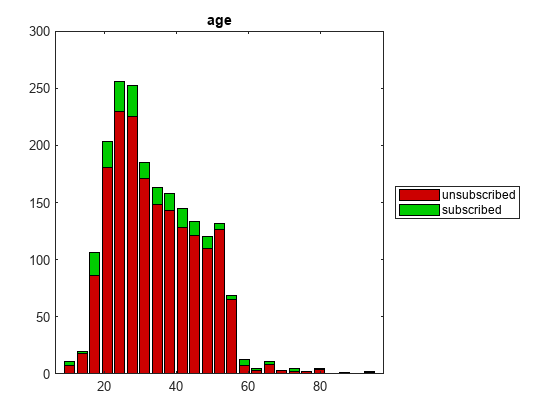

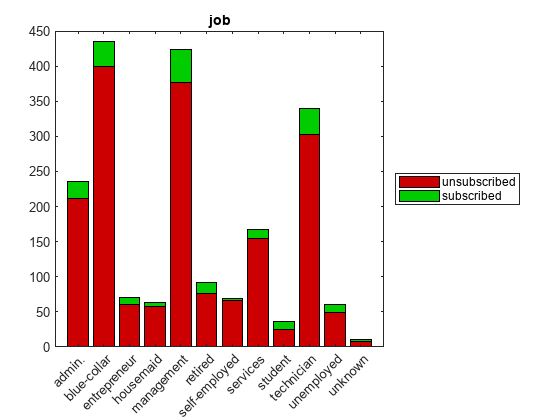

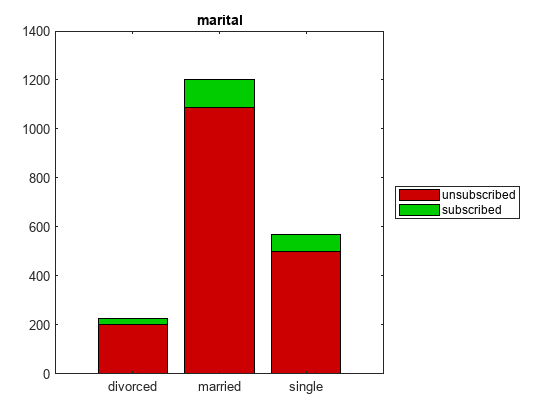

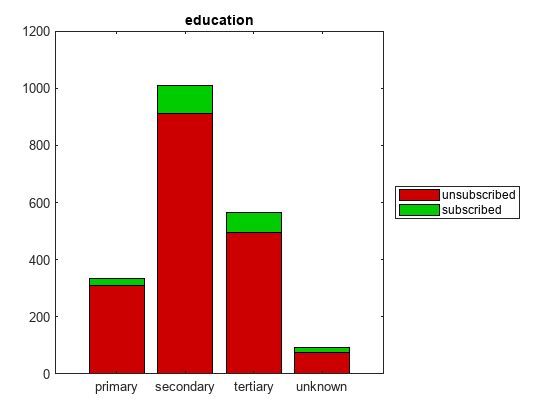

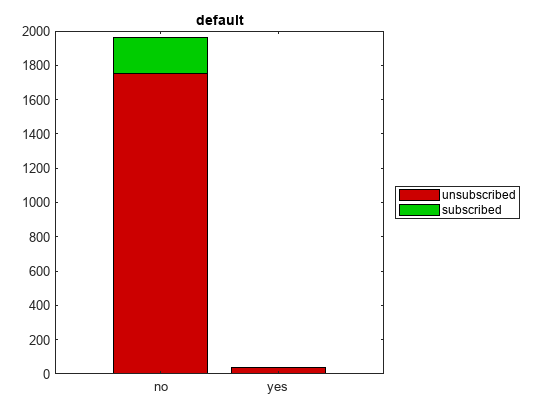

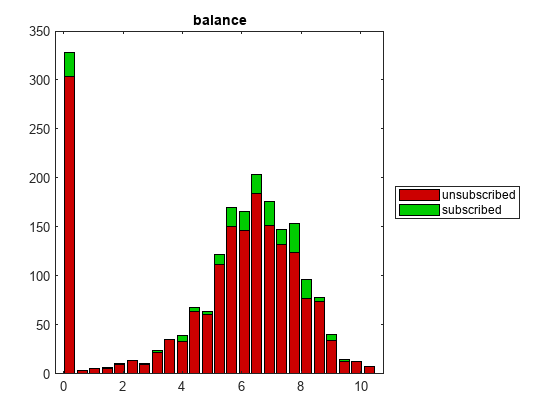

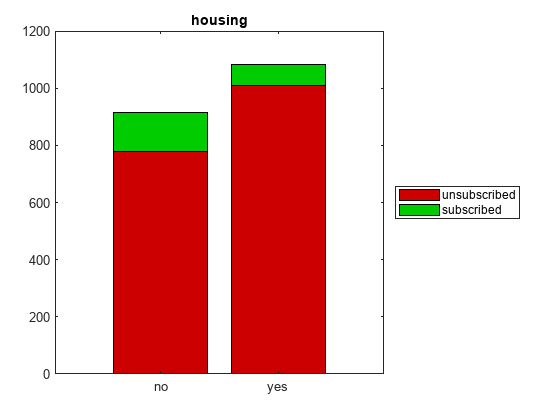

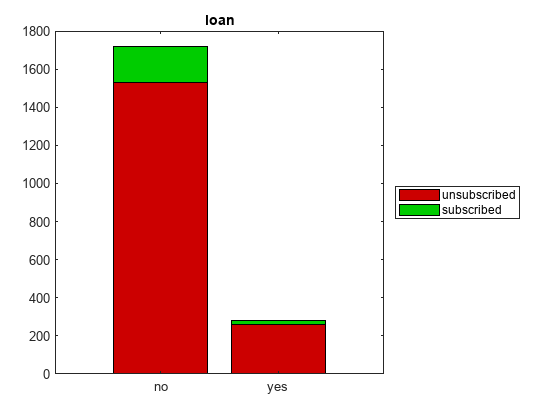

nbins = 25;

for col = 1: width(training_set)
    figure

    if iscategorical(table2array(training_set(:,col)))
        Y(1,:) = countcats( table2array(unsubscribed(:,col)) );
        Y(2,:) = countcats( table2array(  subscribed(:,col)) );

        ba = bar(categorical(categories(table2array(training_set(:,col)))), ...
                 Y', 'stacked', 'FaceColor','flat');
        ba(1).CData = [0.8 0   0];
        ba(2).CData = [0   0.8 0];
        clear Y
    else
        hist_edges = linspace(min(table2array(training_set(:,col))), ...
                              max(table2array(training_set(:,col))), nbins+1);
        plot_edges = linspace(hist_edges(2)/2, (hist_edges(end-1)+hist_edges(end))/2, nbins);
        
        X(1,:) = histcounts( table2array(unsubscribed(:,col)), hist_edges);
        X(2,:) = histcounts( table2array(  subscribed(:,col)), hist_edges);
        
        ba = bar(plot_edges, X', 'stacked', 'FaceColor','flat');
        ba(1).CData = [0.8 0   0];
        ba(2).CData = [0   0.8 0];
    end

    title(training_set.Properties.VariableNames{col})
    if col == 5
        title(' default ')
    end
    legend('unsubscribed','subscribed','Location','eastoutside')
%     saveas(gcf,strcat('figures/Hist_training_', test_set.Properties.VariableNames{col}, '.png') )
end

### % of Subscribed

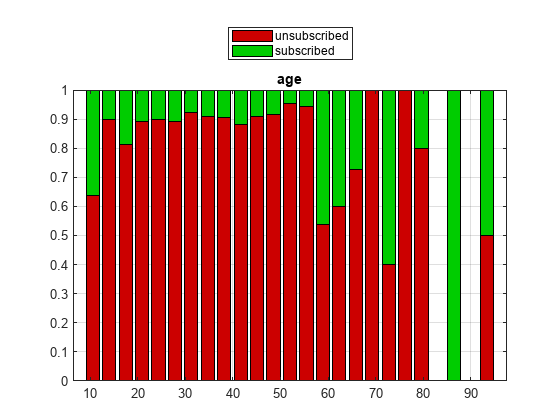

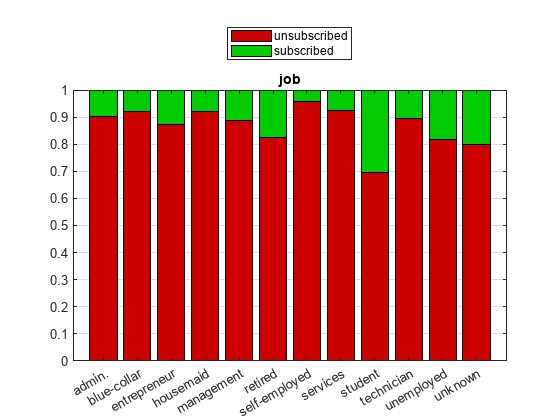

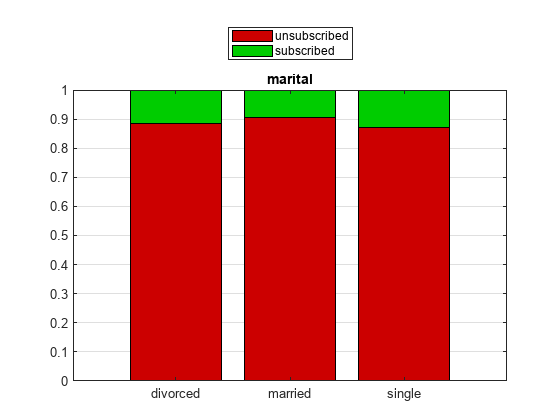

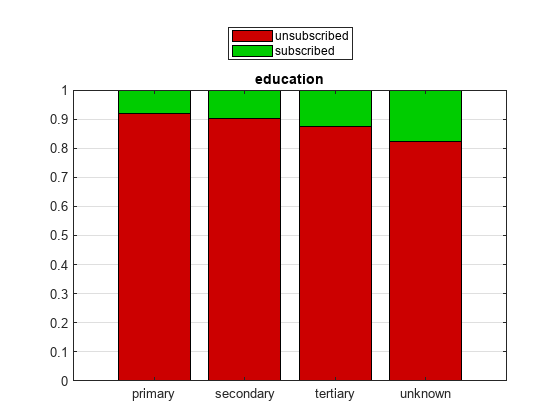

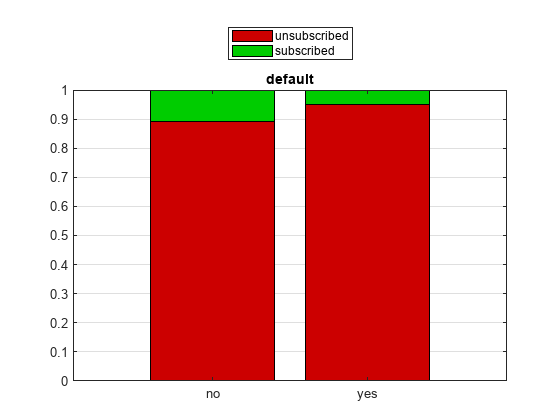

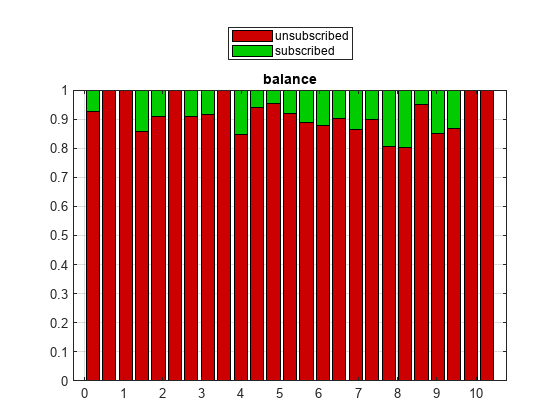

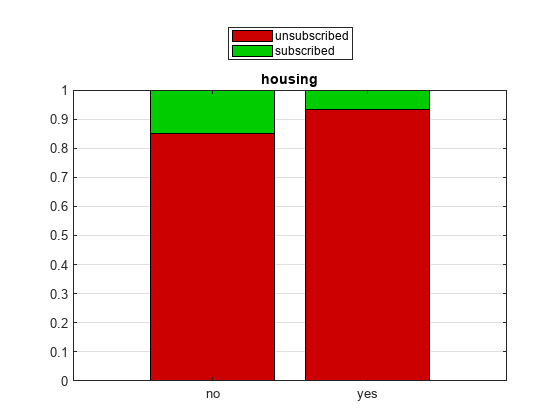

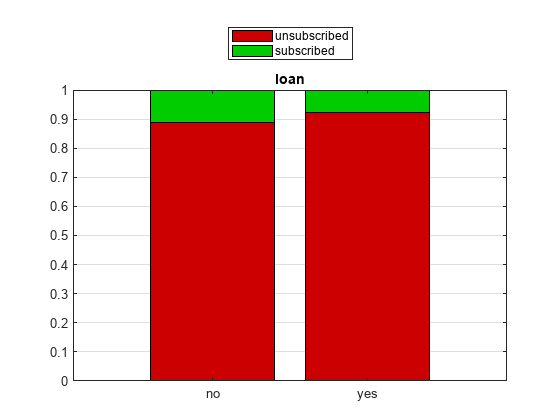

nbins = 25;

for col = 1: width(training_set)
    figure

    if iscategorical(table2array(training_set(:,col)))
        Y(1,:) = countcats( table2array(unsubscribed(:,col)) ) ./ ...
                 countcats( table2array(training_set(:,col)) );
        Y(2,:) = countcats( table2array(  subscribed(:,col)) ) ./ ...
                 countcats( table2array(training_set(:,col)) );

        ba = bar(categorical(categories(table2array(training_set(:,col)))), ...
                 Y', 'stacked', 'FaceColor','flat');
        ba(1).CData = [0.8 0   0];
        ba(2).CData = [0   0.8 0];
        clear Y
    else
        hist_edges = linspace(min(table2array(training_set(:,col))), ...
                              max(table2array(training_set(:,col))), nbins+1);
        plot_edges = linspace(hist_edges(2)/2, (hist_edges(end-1)+hist_edges(end))/2, nbins);
        
        X(1,:) = histcounts( table2array(unsubscribed(:,col)), hist_edges) ./ ...
                 histcounts( table2array(training_set(:,col)), hist_edges);
        X(2,:) = histcounts( table2array(  subscribed(:,col)), hist_edges) ./ ...
                 histcounts( table2array(training_set(:,col)), hist_edges);
        
        ba = bar(plot_edges, X', 'stacked', 'FaceColor','flat');
        ba(1).CData = [0.8 0   0];
        ba(2).CData = [0   0.8 0];
    end

    title(training_set.Properties.VariableNames{col})
    if col == 5
        title(' default ')
    end
    legend('unsubscribed','subscribed','Location','northoutside')
    ylim([0 1])
    grid()
%     saveas(gcf,strcat('figures/Proportion_', test_set.Properties.VariableNames{col}, '.png') )
end

### Histograms of test set

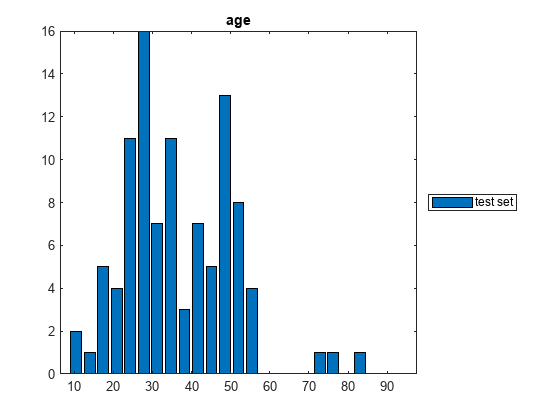

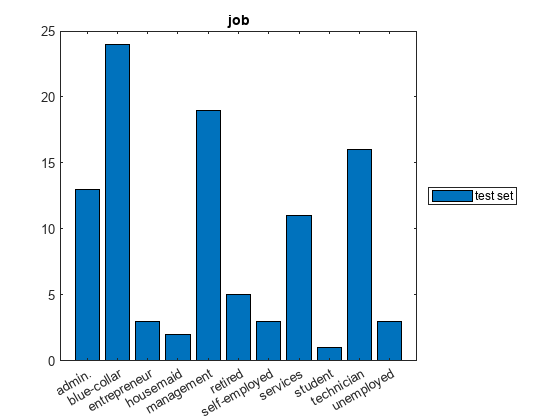

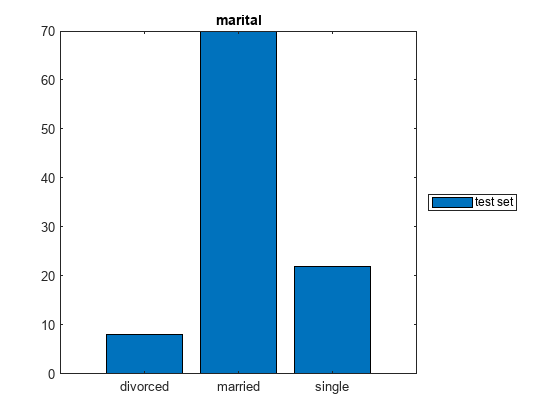

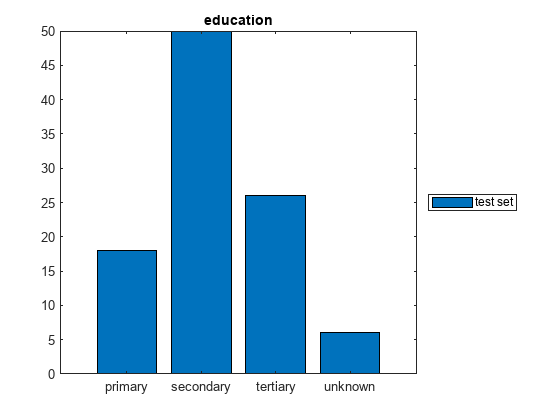

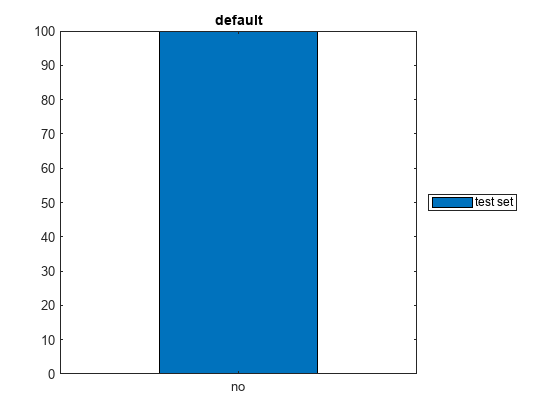

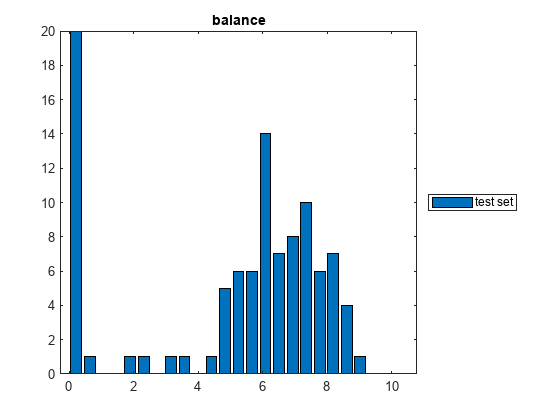

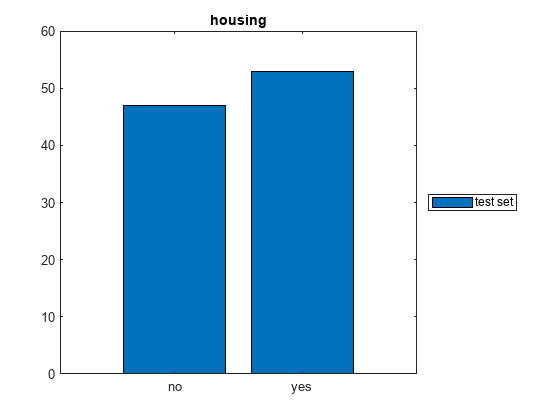

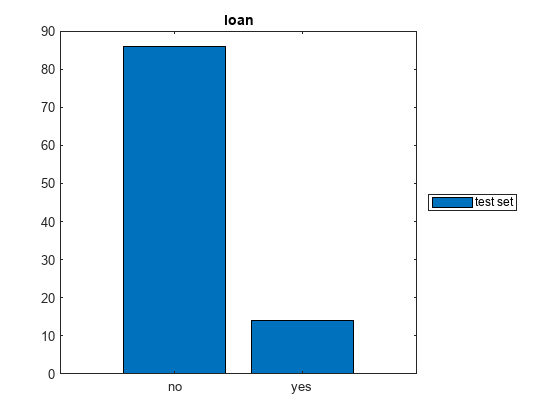

nbins = 25;

for col = 1: width(test_set)
    figure

    if iscategorical(table2array(test_set(:,col)))
        Y = countcats( table2array(test_set(:,col)) );

        ba = bar(categorical(categories(table2array(test_set(:,col)))), ...
                 Y', 'FaceColor','flat');
        clear Y
    else
        hist_edges = linspace(min(table2array(training_set(:,col))), ...
                              max(table2array(training_set(:,col))), nbins+1);
        plot_edges = linspace(hist_edges(2)/2, (hist_edges(end-1)+hist_edges(end))/2, nbins);
        
        X = histcounts( table2array(test_set(:,col)), hist_edges);
        
        ba = bar(plot_edges, X', 'FaceColor','flat');
    end

    title(test_set.Properties.VariableNames{col})
    if col == 5
        title(' default ')
    end
    legend('test set','Location','eastoutside')
%     saveas(gcf,strcat('figures/Hist_test_', test_set.Properties.VariableNames{col}, '.png') )
end

## Gplot of non-categorical variables

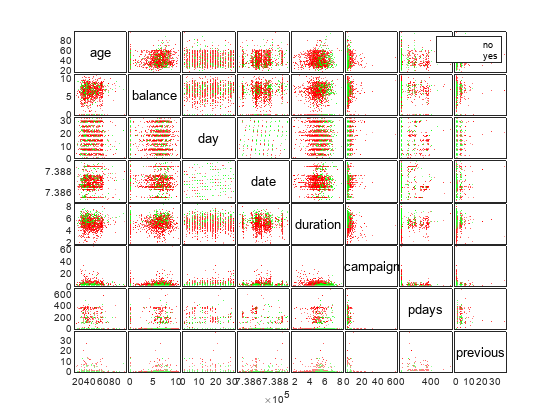

X_ = [training_set.age training_set.balance training_set.day training_set.date, ...
      training_set.duration training_set.campaign training_set.pdays training_set.previous];

xnames = {'age', 'balance', 'day', 'date', 'duration', 'campaign', 'pdays', 'previous'};

figure
[h, ax] = gplotmatrix( X_,[],training_set.subscribed,['r','g'],[],[],[],'variable',xnames);

% saveas(gcf,strcat('figures/gplot_training.png') )

## Clasiffication model: decission tree with all variables

Train a decission tree with the provided dataset, capable of describing the subscription status of the client based on the other variables

tree = fitctree(training_set,'subscribed')

tree =   ClassificationTree
           PredictorNames: {'age'  'job'  'marital'  'education'  'default'  'balance'  'housing'  'loan'  'contact'  'day'  'month'  'duration'  'campaign'  'pdays'  'previous'  'poutcome'  'date'}
             ResponseName: 'subscribed'
    CategoricalPredictors: [2 3 4 5 7 8 9 11 16]
               ClassNames: [no    yes]
           ScoreTransform: 'none'
          NumObservations: 2000


  Properties, Methods


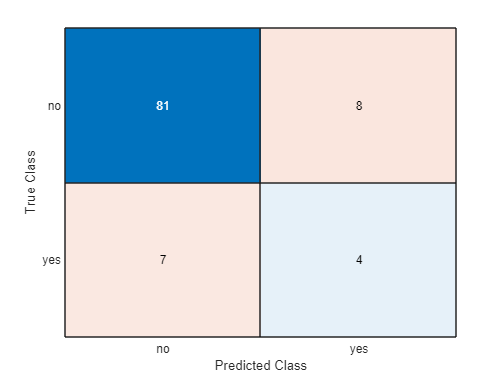


[predictions_Tfull, scores_Tfull] = predict(tree,test_set);
confusionchart(test_set.subscribed,predictions_Tfull)

% saveas(gcf,strcat('figures/Confussion_Tfull.png') )
CrossVal_Tfull = kfoldLoss(crossval(tree))

CrossVal_Tfull = 0.1280


Accuracy_Tfull = accuracy(test_set.subscribed, predictions_Tfull, 'yes', 'no')

Accuracy_Tfull = 0.8500

Recall_Tfull = recall(test_set.subscribed, predictions_Tfull, 'yes', 'no')

Recall_Tfull = 0.3636

Precission_Tfull = precission(test_set.subscribed, predictions_Tfull, 'yes', 'no')

Precission_Tfull = 0.3333

rocObj = rocmetrics(test_set.subscribed, scores_Tfull, tree.ClassNames);
AUC_Tfull = rocObj.AUC(end)

AUC_Tfull = 0.8207

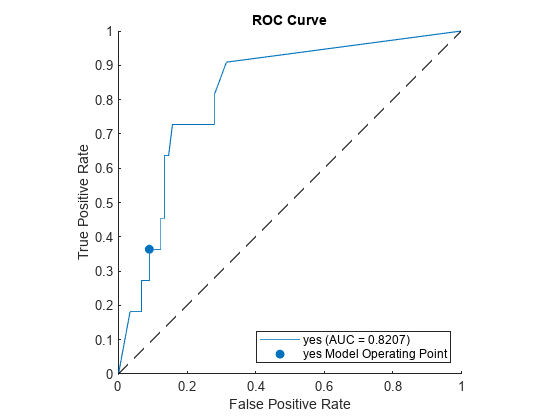

plot(rocObj,ClassNames='yes')
xlim([0,1])
ylim([0,1])

% saveas(gcf,strcat('figures/ROC_Tfull.png') )

### Reduce number of variables

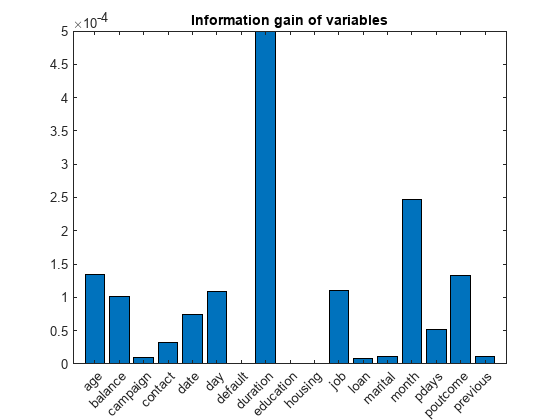

bar(categorical([test_set.Properties.VariableNames(1:end-2),test_set.Properties.VariableNames(end)]), ...
    predictorImportance(tree))
title('Information gain of variables')

% saveas(gcf,strcat('figures/Vars_Tfull.png') )

tree_red = fitctree(removevars(training_set,{'default','education','housing','loan','marital','previous','campaign','date'}),'subscribed')

tree_red =   ClassificationTree
           PredictorNames: {'age'  'job'  'balance'  'contact'  'day'  'month'  'duration'  'pdays'  'poutcome'}
             ResponseName: 'subscribed'
    CategoricalPredictors: [2 4 6 9]
               ClassNames: [no    yes]
           ScoreTransform: 'none'
          NumObservations: 2000


  Properties, Methods


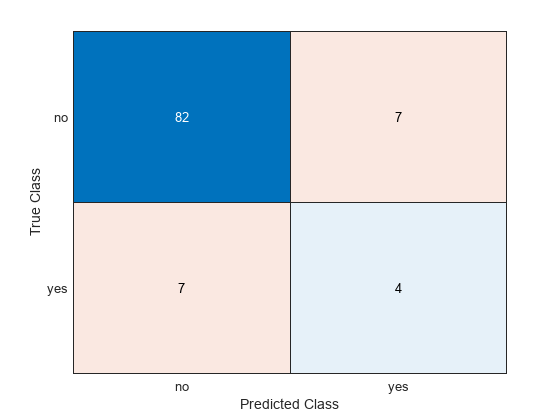


[predictions_Tred, scores_Tred] = predict(tree_red,test_set);
confusionchart(test_set.subscribed,predictions_Tred)

% saveas(gcf,strcat('figures/Confussion_Tred.png') )
CrossVal_Tred = kfoldLoss(crossval(tree_red))

CrossVal_Tred = 0.1270


Accuracy_Tred = accuracy(test_set.subscribed, predictions_Tred, 'yes', 'no')

Accuracy_Tred = 0.8600

Recall_Tred = recall(test_set.subscribed, predictions_Tred, 'yes', 'no')

Recall_Tred = 0.3636

Precission_Tred = precission(test_set.subscribed, predictions_Tred, 'yes', 'no')

Precission_Tred = 0.3636

rocObj = rocmetrics(test_set.subscribed, scores_Tred, tree_red.ClassNames);
AUC_Tred = rocObj.AUC(end)

AUC_Tred = 0.6798

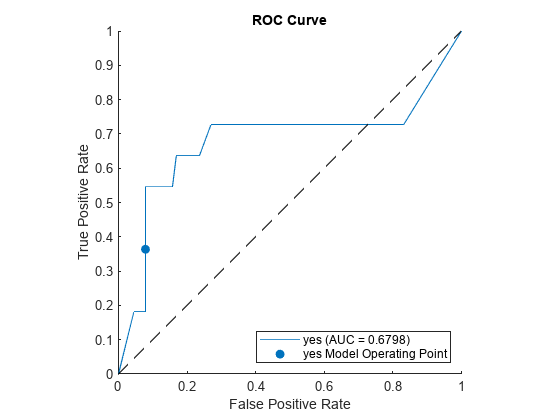

plot(rocObj,ClassNames='yes')
xlim([0,1])
ylim([0,1])

% saveas(gcf,strcat('figures/ROC_Tred.png') )

## Clasiffication model: Naive Bayes

Train a decission tree with the provided dataset, capable of describing the subscription status of the client based on the other variables

NaiveBayes = fitcnb(training_set,'subscribed')

NaiveBayes =   ClassificationNaiveBayes
            PredictorNames: {'age'  'job'  'marital'  'education'  'default'  'balance'  'housing'  'loan'  'contact'  'day'  'month'  'duration'  'campaign'  'pdays'  'previous'  'poutcome'  'date'}
              ResponseName: 'subscribed'
     CategoricalPredictors: [2 3 4 5 7 8 9 11 16]
                ClassNames: [no    yes]
            ScoreTransform: 'none'
           NumObservations: 2000
         DistributionNames: {'normal'  'mvmn'  'mvmn'  'mvmn'  'mvmn'  'normal'  'mvmn'  'mvmn'  'mvmn'  'normal'  'mvmn'  'normal'  'normal'  'normal'  'normal'  'mvmn'  'normal'}
    DistributionParameters: {2×17 cell}
         CategoricalLevels: {[]  [12×1 double]  [3×1 double]  [4×1 double]  [2×1 double]  []  [2×1 double]  [2×1 double]  [3×1 double]  []  [12×1 double]  []  []  []  []  [4×1 double]  []}


  Properties, 

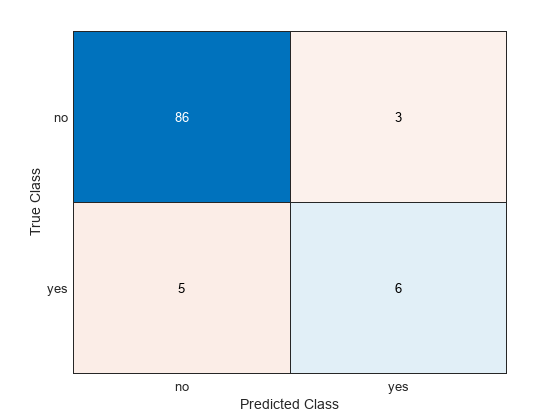


[predictions_NB, scores_NB] = predict(NaiveBayes,test_set);
confusionchart(test_set.subscribed,predictions_NB)

% saveas(gcf,strcat('figures/Confussion_NB.png') )
CrossVal_NB = kfoldLoss(crossval(NaiveBayes))

CrossVal_NB = 0.1250


Accuracy_NB = accuracy(test_set.subscribed, predictions_NB, 'yes', 'no')

Accuracy_NB = 0.9200

Recall_NB = recall(test_set.subscribed, predictions_NB, 'yes', 'no')

Recall_NB = 0.5455

Precission_NB = precission(test_set.subscribed, predictions_NB, 'yes', 'no')

Precission_NB = 0.6667

rocObj = rocmetrics(test_set.subscribed, scores_NB, NaiveBayes.ClassNames);
AUC_NB = rocObj.AUC(end)

AUC_NB = 0.9377

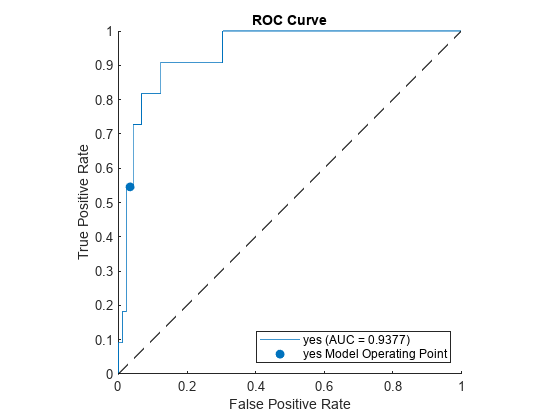

plot(rocObj,ClassNames='yes')
xlim([0,1])
ylim([0,1])

% saveas(gcf,strcat('figures/ROC_NB.png') )

### Include prior probabilities

prob_subscribed = sum(training_set.subscribed == 'yes')/numel(training_set);
% classNames = ['yes', 'no'];
prior = [1-prob_subscribed prob_subscribed];

NB_prior = fitcnb(training_set,'subscribed','Prior',prior)

NB_prior =   ClassificationNaiveBayes
            PredictorNames: {'age'  'job'  'marital'  'education'  'default'  'balance'  'housing'  'loan'  'contact'  'day'  'month'  'duration'  'campaign'  'pdays'  'previous'  'poutcome'  'date'}
              ResponseName: 'subscribed'
     CategoricalPredictors: [2 3 4 5 7 8 9 11 16]
                ClassNames: [no    yes]
            ScoreTransform: 'none'
           NumObservations: 2000
         DistributionNames: {'normal'  'mvmn'  'mvmn'  'mvmn'  'mvmn'  'normal'  'mvmn'  'mvmn'  'mvmn'  'normal'  'mvmn'  'normal'  'normal'  'normal'  'normal'  'mvmn'  'normal'}
    DistributionParameters: {2×17 cell}
         CategoricalLevels: {[]  [12×1 double]  [3×1 double]  [4×1 double]  [2×1 double]  []  [2×1 double]  [2×1 double]  [3×1 double]  []  [12×1 double]  []  []  []  []  [4×1 double]  []}


  Properties, 

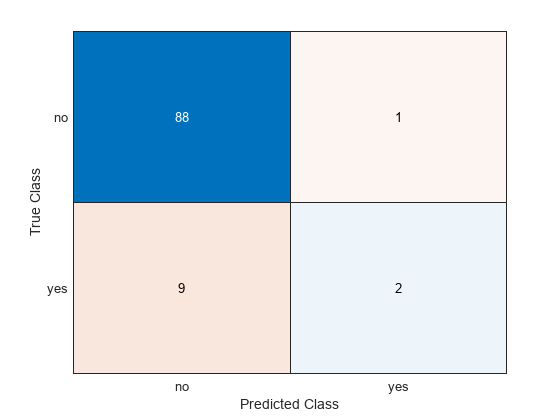

% NB_prior = fitcnb(training_set,'subscribed','ClassNames',classNames,'Prior',prior)

[predictions_NBprior, scores_NBprior] = predict(NB_prior,test_set);
confusionchart(test_set.subscribed,predictions_NBprior)

% saveas(gcf,strcat('figures/Confussion_NBprior.png') )
CrossVal_NBprior = kfoldLoss(crossval(NB_prior))

CrossVal_NBprior = 0.0193


Accuracy_NBprior = accuracy(test_set.subscribed, predictions_NBprior, 'yes', 'no')

Accuracy_NBprior = 0.9000

Recall_NBprior = recall(test_set.subscribed, predictions_NBprior, 'yes', 'no')

Recall_NBprior = 0.1818

Precission_NBprior = precission(test_set.subscribed, predictions_NBprior, 'yes', 'no')

Precission_NBprior = 0.6667

rocObj = rocmetrics(test_set.subscribed, scores_NBprior, NB_prior.ClassNames);
AUC_NBprior = rocObj.AUC(end)

AUC_NBprior = 0.9377

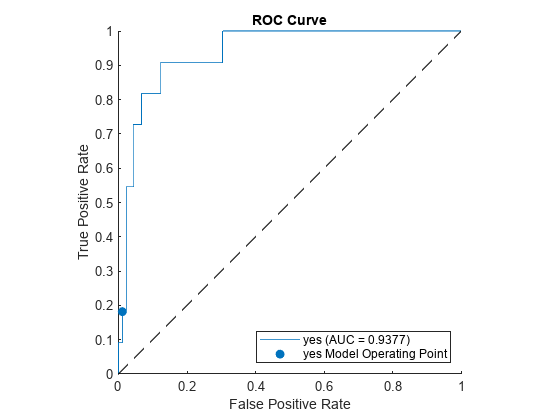

plot(rocObj,ClassNames='yes')
xlim([0,1])
ylim([0,1])

% saveas(gcf,strcat('figures/ROC_NBprior.png') )

### Reduce number of variables

NB_red = fitcnb(removevars(training_set,{'default','education','housing','loan','marital','previous','campaign','date'}),'subscribed')

NB_red =   ClassificationNaiveBayes
            PredictorNames: {'age'  'job'  'balance'  'contact'  'day'  'month'  'duration'  'pdays'  'poutcome'}
              ResponseName: 'subscribed'
     CategoricalPredictors: [2 4 6 9]
                ClassNames: [no    yes]
            ScoreTransform: 'none'
           NumObservations: 2000
         DistributionNames: {'normal'  'mvmn'  'normal'  'mvmn'  'normal'  'mvmn'  'normal'  'normal'  'mvmn'}
    DistributionParameters: {2×9 cell}
         CategoricalLevels: {[]  [12×1 double]  []  [3×1 double]  []  [12×1 double]  []  []  [4×1 double]}


  Properties, Methods


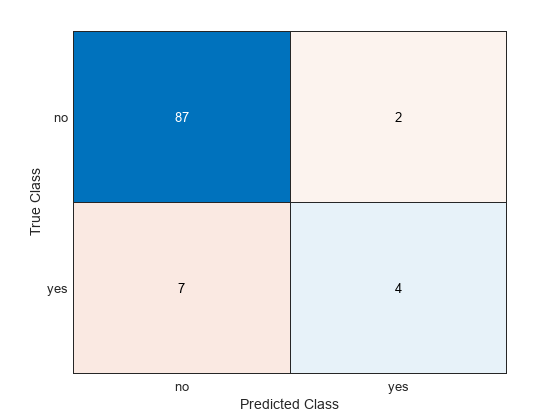


[predictions_NBred, scores_NBred] = predict(NB_red,test_set);
confusionchart(test_set.subscribed,predictions_NBred)

% saveas(gcf,strcat('figures/Confussion_NBred.png') )
CrossVal_NBred = kfoldLoss(crossval(NB_red))

CrossVal_NBred = 0.1075


Accuracy_NBred = accuracy(test_set.subscribed, predictions_NBred, 'yes', 'no')

Accuracy_NBred = 0.9100

Recall_NBred = recall(test_set.subscribed, predictions_NBred, 'yes', 'no')

Recall_NBred = 0.3636

Precission_NBred = precission(test_set.subscribed, predictions_NBred, 'yes', 'no')

Precission_NBred = 0.6667

rocObj = rocmetrics(test_set.subscribed, scores_NBred, NB_red.ClassNames);
AUC_NBred = rocObj.AUC(end)

AUC_NBred = 0.9305

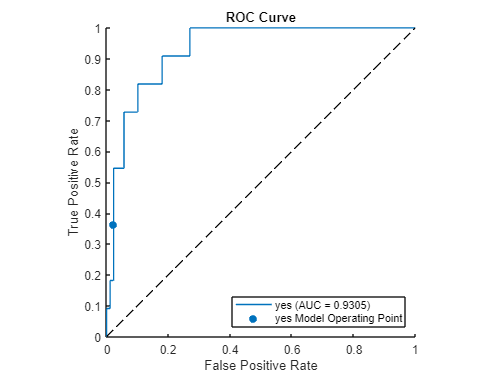

plot(rocObj,ClassNames='yes')
xlim([0,1])
ylim([0,1])

% saveas(gcf,strcat('figures/ROC_NBred.png') )

## Analysis of False Positives and False Negatives

% Indexes of false positives for different methods
i_FP = [test_set.subscribed == 'no' & predictions_Tfull == 'yes', ...
        test_set.subscribed == 'no' & predictions_Tred == 'yes', ...
        test_set.subscribed == 'no' & predictions_NB == 'yes', ...
        test_set.subscribed == 'no' & predictions_NBprior == 'yes', ...
        test_set.subscribed == 'no' & predictions_NBred == 'yes'];

i_FN = [test_set.subscribed == 'yes' & predictions_Tfull == 'no', ...
        test_set.subscribed == 'yes' & predictions_Tred == 'no', ...
        test_set.subscribed == 'yes' & predictions_NB == 'no', ...
        test_set.subscribed == 'yes' & predictions_NBprior == 'no', ...
        test_set.subscribed == 'yes' & predictions_NBred == 'no'];

test_set.FP = sum(i_FP, 2);
test_set.FN = sum(i_FN, 2);

FP_set_any = test_set(test_set.FP>0 & test_set.FP<5,:);
FP_set_all = test_set(test_set.FP==5,:);
FN_set_any = test_set(test_set.FN>0 & test_set.FN<5,:);
FN_set_all = test_set(test_set.FN==5,:);

### Make some graphs

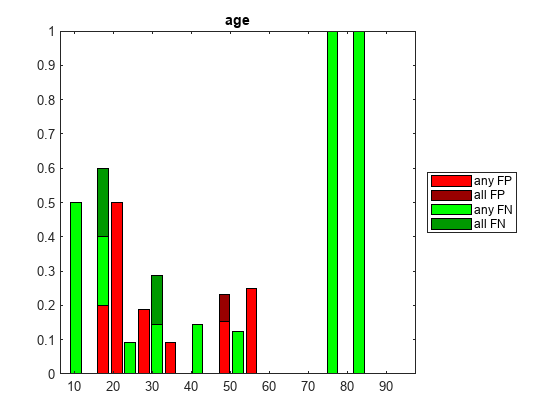

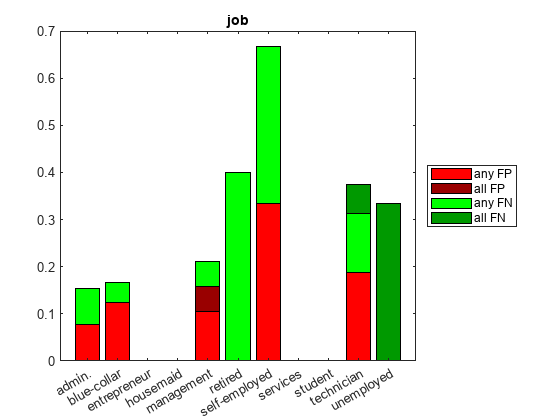

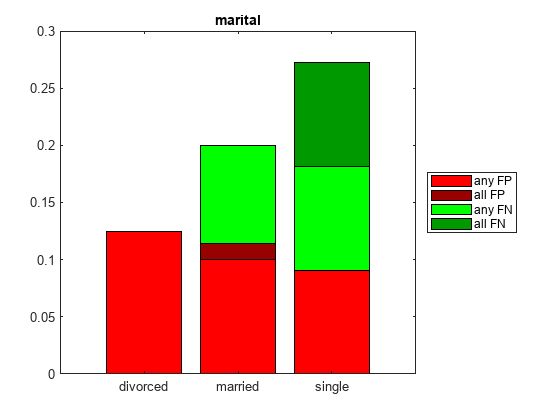

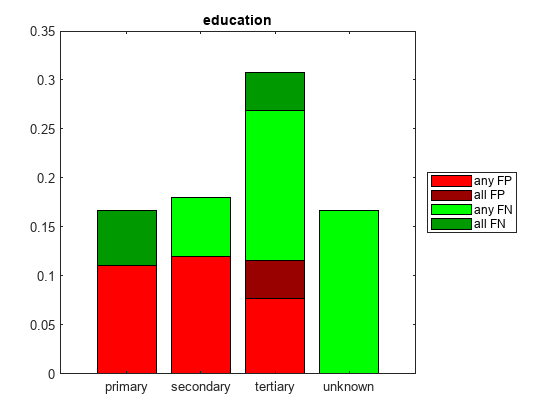

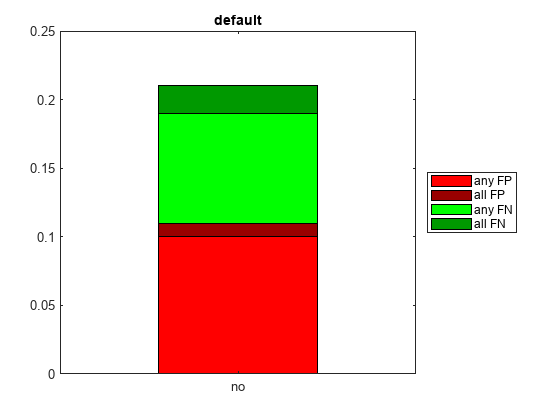

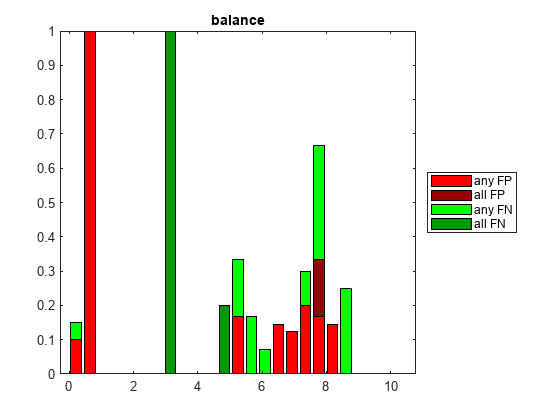

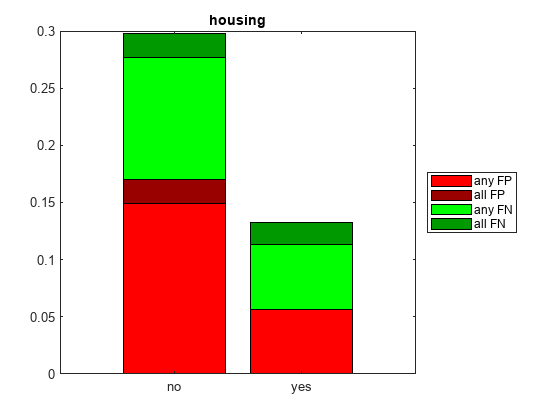

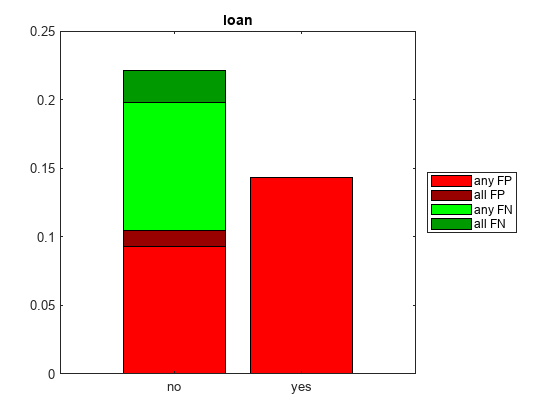

nbins = 25;

for col = 1: width(training_set)
    figure

    if iscategorical(table2array(test_set(:,col)))
        Y(1,:) = countcats( table2array(FP_set_any(:,col)) ) ./ ...
                 countcats( table2array(test_set(:,col)) );
        Y(2,:) = countcats( table2array(FP_set_all(:,col)) )' ./ ...
                 countcats( table2array(test_set(:,col)) );
        Y(3,:) = countcats( table2array(FN_set_any(:,col)) ) ./ ...
                 countcats( table2array(test_set(:,col)) );
        Y(4,:) = countcats( table2array(FN_set_all(:,col)) ) ./ ...
                 countcats( table2array(test_set(:,col)) );

        ba = bar(categorical(categories(table2array(test_set(:,col)))), ...
                 Y', 'stacked', 'FaceColor','flat');
        ba(1).CData = [1.0 0   0];
        ba(2).CData = [0.6 0   0];
        ba(3).CData = [0   1.0 0];
        ba(4).CData = [0   0.6 0];
        clear Y
    else
        hist_edges = linspace(min(table2array(training_set(:,col))), ...
                              max(table2array(training_set(:,col))), nbins+1);
        plot_edges = linspace(hist_edges(2)/2, (hist_edges(end-1)+hist_edges(end))/2, nbins);
        
        X(1,:) = histcounts( table2array(FP_set_any(:,col)), hist_edges) ./ ...
                 histcounts( table2array(test_set(:,col)), hist_edges);
        X(2,:) = histcounts( table2array(FP_set_all(:,col)), hist_edges) ./ ...
                 histcounts( table2array(test_set(:,col)), hist_edges);
        X(3,:) = histcounts( table2array(FN_set_any(:,col)), hist_edges) ./ ...
                 histcounts( table2array(test_set(:,col)), hist_edges);
        X(4,:) = histcounts( table2array(FN_set_all(:,col)), hist_edges) ./ ...
                 histcounts( table2array(test_set(:,col)), hist_edges);
        
        ba = bar(plot_edges, X', 'stacked', 'FaceColor','flat');
        ba(1).CData = [1.0 0   0];
        ba(2).CData = [0.6 0   0];
        ba(3).CData = [0   1.0 0];
        ba(4).CData = [0   0.6 0];
    end

    title(training_set.Properties.VariableNames{col})
    if col == 5
        title(' default ')
    end
    legend('any FP','all FP','any FN','all FN','Location','eastoutside')
%     saveas(gcf,strcat('figures/Hist_FPFN_', test_set.Properties.VariableNames{col}, '.png') )
end